# Algoritmo de Chirp Scaling ET-291

Alunos

DOUGLAS MASSAHIRO KOTSUBO

GUSTAVO HENRIQUE DE QUEIROZ STABILE

RODRIGO DE LIMA FLORINDO

## Aplicação do algoritmo de chirp scaling para alvos pontuais

Seguindo o mesmo procedimento realizado no relatório passado, iremos primeiro validar o uso do CSA para alvos pontuais, antes de aplica-lo em dados brutos reais.

% Inicialização do código limpando o workspace, a janela de comandos e 
% fechando todas a janelas abertas.
clear; clc; close all;

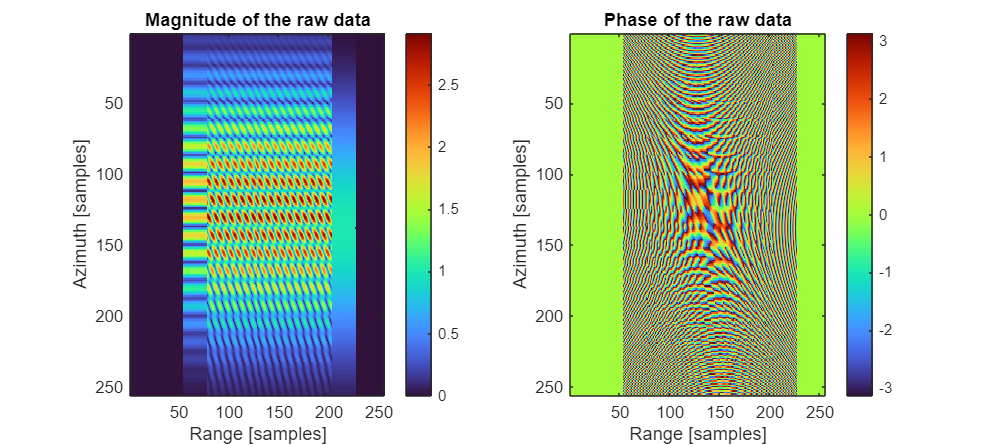

% Execução do código de geração de dados brutos sintéticos para alvos
% pontuais
run("Parametros_alvo_pontual.m");

% Exibição da Magnitude e da Fase dos dados brutos gerados
figure('Position',[0,0,900,400]);
subplot(1,2,1);
imagesc(abs(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Magnitude of the raw data')
subplot(1,2,2);
imagesc(angle(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Phase of the raw data');

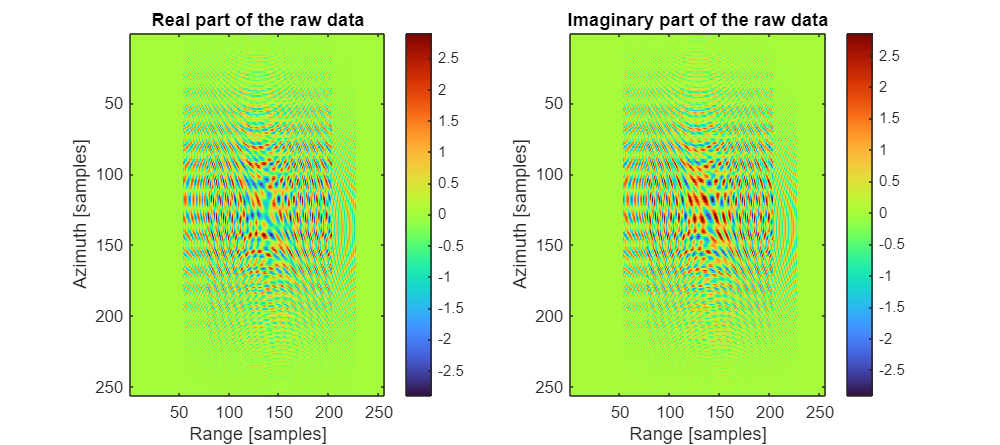


% Exibição das partes reais e imaginárias dos dados brutos sintéticos
figure('Position',[0,0,900,400]);
subplot(1,2,1);
imagesc(real(s0_upchirp));
colorbar;
colormap('turbo');
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Real part of the raw data') 
subplot(1,2,2);
imagesc(imag(s0_upchirp));
colormap('turbo');
colorbar;
xlabel('Range [samples]');
ylabel('Azimuth [samples]');
title('Imaginary part of the raw data');

Conforme Apresentado em [1], O diagrama de blocos de alto nível do Chirp Scaling Algorithm (CSA) é o seguinte:

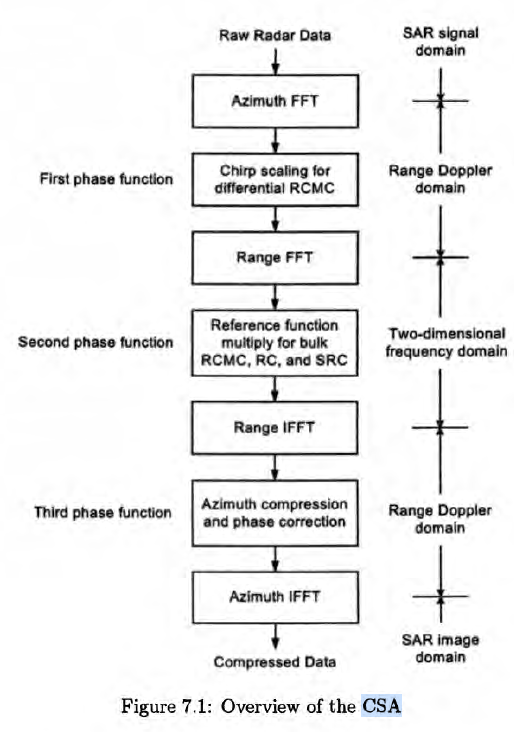

Portanto, é aplicado primeiramente uma FFT em azimute, transformando os dados brutos no domínio do tempo bidimensional para o domínio range-Doppler:

range_Doppler_data = zeros(Naz,Nrg);
for i = 1:Naz
    range_Doppler_data(:,i) = fft(s0_upchirp(:,i));
end

Em seguida, é aplicado Chirp Scaling para correção fina (diferencial) da migração das células em range (RCMC). A forma da função de escalonamento é dada pela equação 7.30 de [1]:


$$s_{\mathrm{sc}} \left(\tau^{\prime } ,f_{\eta } \right)=\exp \left\lbrace \left.j\pi \;K_m \left\lbrack \frac{\;D\left(f_{\eta_{\mathrm{ref}} } \;,V_{r_{\mathrm{ref}} } \right)}{D\left(f_{\eta \;} \;,V_{r_{\mathrm{ref}} } \right)}-1\right\rbrack {\left(\tau^{\prime } \right)}^2 \right)\right\rbrace$$


em que $\tau^{\prime }$ indica o tempo em range, $f_{\eta \;}$denota a frequência em azimute (frequência Doppler), 


$$K_m =\frac{K_r }{1-K_r \frac{{\mathrm{cR}}_0 f_{\eta }^2 }{2V_r^2 f_0^3 D^3 \left(f_{\eta } ,V_r \right)}}$$


representa a taxa FM modificada, que varia em função do parâmetro de migração em range dado por

$D\left(f_{\eta \;} \;,V_r \right)=\sqrt{1-\frac{c^2 f_{\eta }^2 }{4V_r^2 f_0^2 }}$.

Ainda mais, $R_0$ denota o range mais próximo da aquisição da imagem, que pode ser considerado como o range na centróide de shift de frequência Doppler $f_0$ simboliza a banda de frequência da portadora e $V_r$ indica a velocidade efetiva do radar, a qual é considerada invariante no tempo.

com isso,

freq_support_range = linspace(-Fr/2,Fr/2,Nrg);

## Funções usadas no código

%Escrever as funções aqui

## Referências

[1] Cumming, I. G., & Wong, F. H. (2005). *Digital Processing of Synthetic Aperture Radar Data: Algorithms and Implementation*. Artech House.